clc;
clear;

**α) Εξαγωγή Συντελεστών LPC**

[x, Fs] = audioread('voice.wav');
X = frame_wind(x, 256, 0.25);
%[a_voice,g_voice] =lpc_new(X,30);

**β) Εξαγωγή Συντελεστών MFCC**

i) piano

[x, Fs_piano] = audioread('piano_samples.wav');
mf_piano = mfcc(x,Fs_piano);

ii) flute

[x, Fs_flute] = audioread('flute_samples.wav');
mf_flute = mfcc(x,Fs_flute);

iii) cello

[x, Fs_cello] = audioread('cello_samples.wav');
mf_cello = mfcc(x,Fs_cello);

iv) e_guitar

[x, Fs_guitar] = audioread('e_guitar_samples.wav');
mf_guitar = mfcc(x,Fs_guitar);

**γ) Αναγνώριση Μουσικών Οργάνων με συντελεστές MFCC με χρήση προτύπων**

i) piano

m_piano = sum(mf_piano(1:4000),1)/4000;

ii) flute

m_flute = sum(mf_flute(1:4000),1)/4000;

iii) cello

m_cello = sum(mf_cello(1:4000),1)/4000;

iv) e_guitar

m_guitar = sum(mf_guitar(1:4000),1)/4000;

Confusion Matrix

CM = zeros(4,4);

Check the model

i) piano

nRows = size(mf_piano, 1);
for i = (nRows-299):nRows
    tmp = zeros(4);
    tmp(1) = norm(mf_piano(i)-m_piano);
    tmp(2) = norm(mf_piano(i)-m_flute);
    tmp(3) = norm(mf_piano(i)-m_cello);
    tmp(4) = norm(mf_piano(i)-m_guitar);
    [~, index] = min(tmp);
    CM(1,index(1)) = 1 + CM(1,index(1));
end

ii) flute

nRows = size(mf_flute, 1);
for i = (nRows-299):nRows
    tmp = zeros(4);
    tmp(1) = norm(mf_flute(i)-m_piano);
    tmp(2) = norm(mf_flute(i)-m_flute);
    tmp(3) = norm(mf_flute(i)-m_cello);
    tmp(4) = norm(mf_flute(i)-m_guitar);
    [~, index] = min(tmp);
    CM(2,index(1)) = 1 + CM(2,index(1));
end

iii) cello

nRows = size(mf_cello, 1);
for i = (nRows-299):nRows
    tmp = zeros(4);
    tmp(1) = norm(mf_cello(i)-m_piano);
    tmp(2) = norm(mf_cello(i)-m_flute);
    tmp(3) = norm(mf_cello(i)-m_cello);
    tmp(4) = norm(mf_cello(i)-m_guitar);
    [~, index] = min(tmp);
    CM(3,index(1)) = 1 + CM(3,index(1));
end

iv) guitar

nRows = size(mf_guitar, 1);
for i = (nRows-299):nRows
    tmp = zeros(4);
    tmp(1) = norm(mf_guitar(i)-m_piano);
    tmp(2) = norm(mf_guitar(i)-m_flute);
    tmp(3) = norm(mf_guitar(i)-m_cello);
    tmp(4) = norm(mf_guitar(i)-m_guitar);
    [~, index] = min(tmp);
    CM(4,index(1)) = 1 + CM(4,index(1));
end

Plot confusion matrix

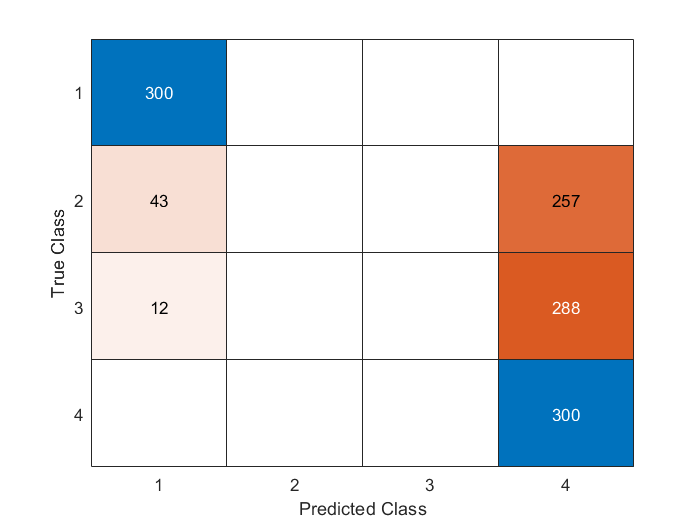

figure
confusionchart(CM)